Subscript indices must either be real positive integers or logicals.

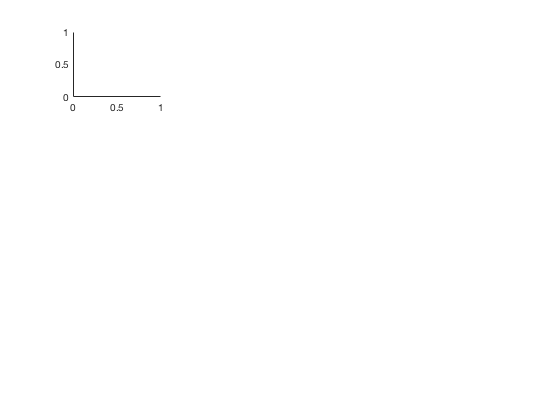

for k = [1:72]

    k2str = num2str(k);
    
    %pull two-threshold events from dataFrame (originally in datpoints, converted to seconds)
    a = dataFrame(k).starts;
    a = a';
    b = dataFrame(k).ends;
    b = b';
    evJP = floor([a b]/512);
    
    clear a b
    
    %pull bergstrom events from SigSumm (originally in seconds, leave as seconds)
    
    % a1 = SigSumm(k).spike;
    % a1= SigSumm(k).seizure;
    a1 = SigSumm(k).abnormal;
    
    evRBsp = floor(a1);
    
    clear a1 a2 a3;
    
    [m, ~] = size(evJP);
    [n, ~] = size(evRBsp);
    
    % This loop pumps out a m x n (jp event# x rb event#) matrix
    % with zero at the points where there is agreement. All
    % other positions will be zeros. 
    % For example: if jp event #2 is the same event as rb event #6, 
    % there will be a one at position (2,6) in the matrix. 
    
    jpRB = zeros (m,n);
    
    for mm = 1:m
    
        jpEvent = evJP(mm,1):evJP(mm,2); 
        jpEvent = jpEvent';
        
            for nn = 1:n
            
                rbEventSP = evRBsp(nn,1):evRBsp(nn,2);
                cSP = intersect(jpEvent,rbEventSP);
                jpRB(mm,nn) = isempty(cSP);
                
                clear cSP
            
            end
        
    end
    
    
    jpSolo = zeros(m,2);
    
    for mm = 1:m  
        jpSolo(mm,1) = sum(jpRB(mm,:))-n;
    end
    
    jpNo = zeros(length(jpSolo),1);
    
    for r = 1:length(jpSolo)
        if jpSolo(r) == 0;
        jpNo(r) = 1;
        else jpNo(r) = 0;
        end
    end
    
    jpNoOverlap = find(jpNo);
    
    
    rbSolo = zeros(n,1);
    
    for nn = 1:n
        rbSolo(nn) = sum(jpRB(:,nn))-m;
    end
    
    rbNo = zeros(length(rbSolo),1);
    
    for r = 1:length(rbSolo)
        if rbSolo(r) == 0;
            rbNo(r,:) = 1;
        else rbNo(r,:) = 0;
        end
    end
    
    
    rbNoOverlap = find(rbNo);
    
    
    % at this point, jpNoOverlap is a vector that has 
    % the index of events that are NOT found in rab events 
    % and rbNoOverlap is the same for jp events
    
    
    fileID = SigSumm(k).fileID;
    EEG = dataFrame(k).signal;
    
    a = dataFrame(k).starts;
    a = a';
    b = dataFrame(k).ends;
    b = b';
    
    %a1 = SigSumm(k).spike;
    %a1 = SigSumm(k).seizure;
    a1 = SigSumm(k).abnormal;
    a1 = a1*512;
    
    p = length(jpNoOverlap);
    
    pRow = 4;
    pCol = 4;
    
    
    for pp = 1:p %change as needed to replot events
    
        n = ceil(pp/(pRow*pCol))- 1;
        nn = (pRow*pCol)*n;
        mm = pp - nn; 
        
        jpPlot = a(jpNoOverlap(pp)):b(jpNoOverlap(pp));
        wholePlot = jpPlot(1)-500:jpPlot(1)+512;
        
        XMIN = jpPlot(1)/512 - 1;
        XMAX = jpPlot(1)/512 + 1;
        YMIN = -15;
        YMAX = 15;
        
        subplot (pRow, pCol, mm)
        plot(wholePlot/512,EEG(wholePlot),'k', 'LineWidth',0.25)
        hold on
        
        plot(jpPlot/512, EEG(jpPlot),'r','LineWidth',1.0)
        axis([XMIN XMAX YMIN YMAX])
        box off
        
        if pp ~= 1
            axis off
        else end
        
        mStr = num2str (pp);
        
        if mm == pRow*pCol || pp == p
            saveas(gcf, ['jp_' k2str '_' fileID '_' mStr '.eps'], 'epsc')
            close (gcf)
        else 
        end
        
        
        clear n nn mm rbPlot jpPlot XMIN XMAX...
        YMIN YMAX mStr
    end
    
    clear p 
    
    p = length(rbNoOverlap);
    
    if p > 100
      p = 100;
    else 
    end
    
    for pp = 1:p %change as needed to replot events
        
        
        n = ceil(pp/(pRow*pCol))- 1;
        nn = (pRow*pCol)*n;
        mm = pp - nn; 
        
        rbPlot = a1(rbNoOverlap(pp),1):a1(rbNoOverlap(pp),2);
      
        wholePlot = rbPlot(1)-500:rbPlot(1)+512;
      
        
        XMIN = rbPlot(1)/512 - 1;
        XMAX = rbPlot(1)/512 + 1;
        YMIN = -15;
        YMAX = 15;
        
        subplot (pRow, pCol, mm)
        plot(wholePlot/512,EEG(wholePlot),'k', 'LineWidth',0.25)
        hold on
        plot (rbPlot/512, EEG(rbPlot),'c','LineWidth',1.0)
        axis([XMIN XMAX YMIN YMAX])
        box off
        
        if pp ~= 1
          axis off
        else end
        
        mStr = num2str (pp);
       
        if mm == pRow*pCol || pp == p
            saveas(gcf, ['rb_' k2str '_' fileID '_' mStr '.eps'], 'epsc')
            close (gcf)
        else 
        end
        
        
        clear n nn mm m rbPlot jpPlot XMIN XMAX...
        YMIN YMAX mStr
    end
    
    clear a a1 b EEG jpNoOverlap rbNoOverlap p pCol pRow fileID k2str pp

end